Laboratory work No.2

Datasets, plotting the graphs 

FEIS AS-57 Chernookiy Ilya 

Create a dataset array from Fisher's iris data and add a description and plot some graphs, let's check it on the example of Dataset hospital: 

load iris_dataset
load hospital
hospital.Properties.VarNames{2} = 'Gender';
hospital = sortrows(hospital,'BloodPressure','ascend');
hospital = hospital(:,[1:3 5 4 6:end]);
hospital(:,'Weight') = [];
hospital.LastName{101} = 'MARTIN';

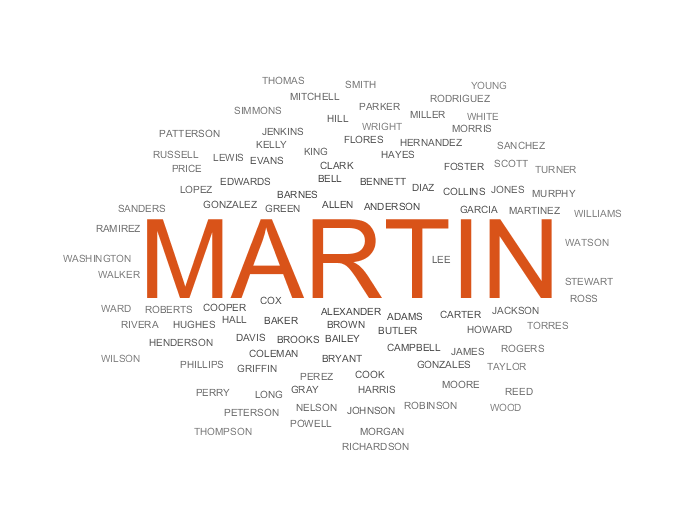

hospital.Gender(101) = 'Male';
hospital.Age(101) = 45;
hospital.BloodPressure(101,1) = 120;
hospital.BloodPressure(101,2) = 70;
hospital.Properties.ObsNames{101} = 'PPG-151';

hospital = sortrows(hospital,'LastName','ascend');
hospital = sortrows(hospital,'Age','ascend');
hospital = sortrows(hospital,'Smoker','ascend');

wordcloud(hospital.LastName);

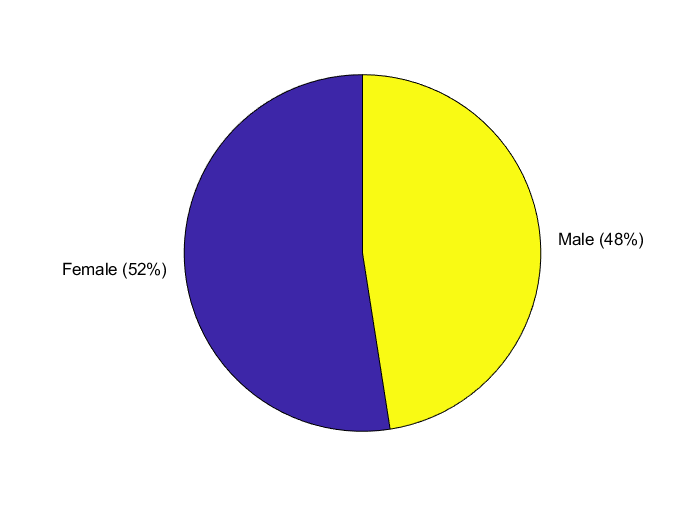

pie(hospital.Gender)

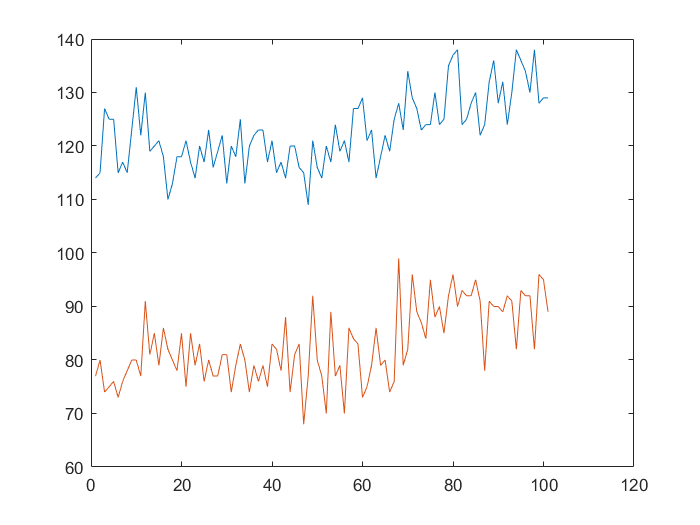

plot(hospital.BloodPressure,'DisplayName','hospital.BloodPressure')

Plotting the graphs: